## Chapter 1: Feedback Linearisation Control

### Chapter 1.1 Lie Derivative

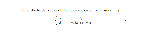

% The plant is considered bellow
close all;
figure(1)
imshow(imread("plant_siso_system.png"));


syms x1 x2 u % symbolic presentation
fx=[x2;-sin(x1)];
g=[0;1];
x=[x1 x2];
h=x1;
LH=LieDerivative(h,x)

$$LH = \left(\begin{array}{cc} 1 & 0 \end{array}\right)$$

[lhf lhg]=solvelieder(LH,fx,g)

$$lhf = x_{2}$$

$$lhg = 0$$

### Chapter 1.2 Feedback Linearisation Controller Examples

clear all;clc
disp('−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−');

−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−


disp('The Nonlinear systems should ');

The Nonlinear systems should 


disp('be written in the following form ');

be written in the following form 


disp('State space equations x=f(x)+g(x)u');

State space equations x=f(x)+g(x)u


disp('−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−');

−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−


% The your system contains
% Input the extra parameters
par=input('Parameters ','s');
eval(sprintf('syms %s',par));
parameters=sprintf('%s',par)


parameters =

  1×0 empty char array



%% Declare how many states and inputs
n=input('Number of states:=');
nin=input('Number of inputs:=');
x=sym(zeros(1,n));
u=sym(zeros(1,nin));
for j=1:n
    eval(sprintf('syms x%d',j))
    x(:,j)=sprintf('x%d',j);
end
for k=1:nin
    eval(sprintf('syms u%d',k));
    u(:,k)=sprintf('u%d',k);
end
% Enter the functions from the keyboard
f=input('The vector f(x):=','s');
g=input('The vector g(x):=','s');
Hc=input('The output variables:=','s');
%Represent all the functions
%f(x), g(x) and h(x) on a symbolic format
fx=str2sym(f);
g=str2sym(g);
Hc=str2sym(Hc); %
% Use the inoutfeedbacklinearization.m
% programm to generate the desired functions
[Lhf Lhg]=inoutfeedbacklinearization(fx,g,Hc,x)

The relative degree of h1
equal:=1
The relative degree of h2
equal:=1


$$Lhf = \left(\begin{array}{c} x_{1}+x_{1}\,x_{2}\\ -\sin\left(x_{1}\right) \end{array}\right)$$

$$Lhg = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

### Chapter 1.3 Illustrative examples

#### 1.3.1 Aircraft altitude dynamics

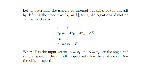

% The plant is considered bellow
close all;
figure(1)
imshow(imread("aircraft_motion_equations.png"));


clear all;clc
disp('−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−');

−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−


disp('The Nonlinear systems should ');

The Nonlinear systems should 


disp('be written in the following form ');

be written in the following form 


disp('State space equations x=f(x)+g(x)u');

State space equations x=f(x)+g(x)u


disp('−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−');

−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−


% The your system contains
% Input the extra parameters
par=input('Parameters ','s');
eval(sprintf('syms %s',par));
parameters=sprintf('%s',par)


parameters =

  1×0 empty char array



%% Declare how many states and inputs
n=input('Number of states:=');
nin=input('Number of inputs:=');
x=sym(zeros(1,n));
u=sym(zeros(1,nin));
for j=1:n
    eval(sprintf('syms x%d',j))
    x(:,j)=sprintf('x%d',j);
end
for k=1:nin
    eval(sprintf('syms u%d',k));
    u(:,k)=sprintf('u%d',k);
end
% Enter the functions from the keyboard
f=input('The vector f(x):=','s');
g=input('The vector g(x):=','s');
Hc=input('The output variables:=','s');
%Represent all the functions
%f(x), g(x) and h(x) on a symbolic format
fx=str2sym(f);
g=str2sym(g);
Hc=str2sym(Hc); %
% Use the inoutfeedbacklinearization.m
% programm to generate the desired functions
[Lhf Lhg]=inoutfeedbacklinearization(fx,g,Hc,x)

The relative degree of h1
equal:=2


$$Lhf = 6\,x_{1}$$

$$Lhg = -1$$

#### 1.3.2 Asynchronous motor speed control

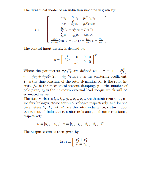

% The plant is considered bellow
close all;
figure(1)
imshow(imread("asynchronous_motor_dynamical_model.png"));


clear all;clc
disp('−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−');

−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−


disp('The Nonlinear systems should ');

The Nonlinear systems should 


disp('be written in the following form ');

be written in the following form 


disp('State space equations x=f(x)+g(x)u');

State space equations x=f(x)+g(x)u


disp('−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−');

−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−


% The your system contains
% Input the extra parameters
par=input('Parameters ','s');
eval(sprintf('syms %s',par));
parameters=sprintf('%s',par)

parameters = 'T1 gamma K Tr p fm Jm Lr M Ls sigma'

%% Declare how many states and inputs
n=input('Number of states:=');
nin=input('Number of inputs:=');
x=sym(zeros(1,n));
u=sym(zeros(1,nin));
for j=1:n
    eval(sprintf('syms x%d',j))
    x(:,j)=sprintf('x%d',j);
end
for k=1:nin
    eval(sprintf('syms u%d',k));
    u(:,k)=sprintf('u%d',k);
end
% Enter the functions from the keyboard
f=input('The vector f(x):=','s');
g=input('The vector g(x):=','s');
Hc=input('The output variables:=','s');
%Represent all the functions
%f(x), g(x) and h(x) on a symbolic format
fx=str2sym(f);
g=str2sym(g);
Hc=str2sym(Hc); %
% Use the inoutfeedbacklinearization.m
% programm to generate the desired functions
[Lhf Lhg]=inoutfeedbacklinearization(fx,g,Hc,x)

The relative degree of h1
equal:=2
The relative degree of h2
equal:=2


$$Lhf = \begin{array}{l} \left(\begin{array}{c} \left(\frac{4\,x_{3}}{\mathrm{Tr}}-\frac{2\,M\,x_{1}}{\mathrm{Tr}}\right)\,\sigma_{4}-\left(\frac{4\,x_{4}}{\mathrm{Tr}}-\frac{2\,M\,x_{2}}{\mathrm{Tr}}\right)\,\sigma_{3}+\frac{2\,M\,x_{3}\,\sigma_{2}}{\mathrm{Tr}}-\frac{2\,M\,x_{4}\,\sigma_{1}}{\mathrm{Tr}}\\ \frac{\mathrm{fm}\,\left(\frac{T_{1}}{\mathrm{Jm}}+\frac{\mathrm{fm}\,x_{5}}{\mathrm{Jm}}+\frac{M\,p\,\left(x_{1}\,x_{4}-x_{2}\,x_{3}\right)}{\mathrm{Jm}\,\mathrm{Lr}}\right)}{\mathrm{Jm}}-\frac{M\,p\,x_{3}\,\sigma_{1}}{\mathrm{Jm}\,\mathrm{Lr}}-\frac{M\,p\,x_{4}\,\sigma_{2}}{\mathrm{Jm}\,\mathrm{Lr}}-\frac{M\,p\,x_{1}\,\sigma_{3}}{\mathrm{Jm}\,\mathrm{Lr}}-\frac{M\,p\,x_{2}\,\sigma_{4}}{\mathrm{Jm}\,\mathrm{Lr}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\gamma \,x_{2}-\frac{K\,x_{4}}{\mathrm{Tr}}+K\,p\,x_{3}\,x_{5}\\ \sigma_{2}=\frac{K\,x_{3}}{\mathrm{Tr}}-\gamma \,x_{1}+K\,p\,x_{4}\,x_{5}\\ \sigma_{3}=p\,x_{3}\,x_{5}-\frac{x_{4}}{\mathrm{Tr}}+\frac{M\,x_{2}}{\mathrm{Tr}}\\ \sigma_{4}=\frac{x_{3}}{\mathrm{Tr}}+p\,x_{4}\,x_{5}-\frac{M\,x_{1}}{\mathrm{Tr}} \end{array}$$

$$Lhg = \left(\begin{array}{cc} \frac{2\,M\,x_{3}}{\mathrm{Ls}\,\mathrm{Tr}\,\sigma } & \frac{2\,M\,x_{4}}{\mathrm{Ls}\,\mathrm{Tr}\,\sigma }\\ -\frac{M\,p\,x_{4}}{\mathrm{Jm}\,\mathrm{Lr}\,\mathrm{Ls}\,\sigma } & \frac{M\,p\,x_{3}}{\mathrm{Jm}\,\mathrm{Lr}\,\mathrm{Ls}\,\sigma } \end{array}\right)$$

## Chapter 2 Sliding Mode Control

### 2.1 Sliding mode control examples for SISO Systems

#### 2.1.1 Van der Pol system

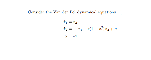

% The plant is considered bellow
close all;
figure(1)
imshow(imread("van_der_pol_dynamical_equations.png"));


clear all;clc
disp('−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−');

−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−


disp('The Nonlinear systems should be written in the following form');

The Nonlinear systems should be written in the following form


disp('−−Sliding Mode Controller for a class of Nonlinear systems−−');

−−Sliding Mode Controller for a class of Nonlinear systems−−


disp(' State space equations x=f(x)+gu ');

 State space equations x=f(x)+gu 


disp('−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−');

−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−


n=input('Number of states:=');
nin=input('Number of inputs:=');
x=sym(zeros(1,n));
u=sym(zeros(1,nin));
par=input('Parameters ','s');
eval(sprintf('syms %s',par));
parameters=sprintf('%s',par)

parameters = 'e'

for j=1:n
    eval(sprintf('syms x%d',j))
    x(:,j)=sprintf('x%d',j);
end
for k=1:nin
    eval(sprintf('syms u%d',k));
    u(:,k)=sprintf('u%d',k);
end
syms u1
f=input('The vector f(x):=','s');
g=input('The vector g(x):=','s');
Hc=input('The output variables:=','s');
f=str2sym(f);Hc=str2sym(Hc);g=str2sym(g);
[Lhf,Lhg,dh,L,u,r]=NonContSidFed(f,g,Hc,x,u1);
[Surf,dSurf,dd,K,Uc]=SlidingModeTerms(Hc,L,r,Lhg);

The sliding mode control law for SISO systems=:


$$Uc = \mathrm{d3yr}+x_{1}+\mathrm{kp}\,\mathrm{sgnS}+k_{1}\,\left(\mathrm{d2yr}-x_{2}\right)+e\,x_{2}\,\left({x_{1}}^{2}-1\right)$$

The Sliding mode surface:=


$$Surf = \mathrm{d2yr}-x_{2}+k_{1}\,\left(\mathrm{d1yr}-x_{1}\right)$$

The derivative of Sliding mode surface:=


$$dSurf = \mathrm{d3yr}+x_{1}+k_{1}\,\left(\mathrm{d2yr}-x_{2}\right)+e\,x_{2}\,\left({x_{1}}^{2}-1\right)$$

#### 2.1.1 DC motor angular position control

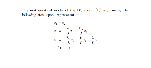

% The plant is considered bellow
close all;
figure(1)
imshow(imread("DC_motor_mathematical_model.png"));


clear all;clc
disp('−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−');

−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−


disp('The Nonlinear systems should be written in the following form');

The Nonlinear systems should be written in the following form


disp('−−Sliding Mode Controller for a class of Nonlinear systems−−');

−−Sliding Mode Controller for a class of Nonlinear systems−−


disp(' State space equations x=f(x)+gu ');

 State space equations x=f(x)+gu 


disp('−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−');

−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−


n=input('Number of states:=');
nin=input('Number of inputs:=');
x=sym(zeros(1,n));
u=sym(zeros(1,nin));
par=input('Parameters ','s');
eval(sprintf('syms %s',par));
parameters=sprintf('%s',par)

parameters = 'b J km ke L R'

for j=1:n
    eval(sprintf('syms x%d',j))
    x(:,j)=sprintf('x%d',j);
end
for k=1:nin
    eval(sprintf('syms u%d',k));
    u(:,k)=sprintf('u%d',k);
end
syms u1
f=input('The vector f(x):=','s');
g=input('The vector g(x):=','s');
Hc=input('The output variables:=','s');
f=str2sym(f);Hc=str2sym(Hc);g=str2sym(g);
[Lhf,Lhg,dh,L,u,r]=NonContSidFed(f,g,Hc,x,u1);
[Surf,dSurf,dd,K,Uc]=SlidingModeTerms(Hc,L,r,Lhg);

The sliding mode control law for SISO systems=:


$$Uc = \mathrm{d4yr}+\mathrm{kp}\,\mathrm{sgnS}+k_{1}\,\left(\mathrm{d3yr}+\frac{b\,x_{2}}{J}-\frac{\mathrm{km}\,x_{3}}{J}\right)+k_{2}\,\left(\mathrm{d2yr}-x_{2}\right)+\frac{\mathrm{km}\,\left(\frac{R\,x_{3}}{L}+\frac{\mathrm{ke}\,x_{2}}{L}\right)}{J}-\frac{b\,\left(\frac{b\,x_{2}}{J}-\frac{\mathrm{km}\,x_{3}}{J}\right)}{J}$$

The Sliding mode surface:=


$$Surf = \mathrm{d3yr}+k_{2}\,\left(\mathrm{d1yr}-x_{1}\right)+k_{1}\,\left(\mathrm{d2yr}-x_{2}\right)+\frac{b\,x_{2}}{J}-\frac{\mathrm{km}\,x_{3}}{J}$$

The derivative of Sliding mode surface:=


$$dSurf = \mathrm{d4yr}+k_{1}\,\left(\mathrm{d3yr}+\frac{b\,x_{2}}{J}-\frac{\mathrm{km}\,x_{3}}{J}\right)+k_{2}\,\left(\mathrm{d2yr}-x_{2}\right)+\frac{\mathrm{km}\,\left(\frac{R\,x_{3}}{L}+\frac{\mathrm{ke}\,x_{2}}{L}\right)}{J}-\frac{b\,\left(\frac{b\,x_{2}}{J}-\frac{\mathrm{km}\,x_{3}}{J}\right)}{J}$$

### 2.2 Sliding mode control examples for MIMO Systems

#### 2.2.1 Permanent magnet synchronous motor speed control

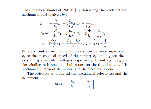

% The plant is considered bellow
close all;
figure(1)
imshow(imread("PMSM_dynamical_model.png"));



clear all;clc
disp('−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−');

−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−


disp('The Nonlinear systems should be written in the following form');

The Nonlinear systems should be written in the following form


disp('−−Sliding Mode Controller for MIMO Nonlinear systems−−');

−−Sliding Mode Controller for MIMO Nonlinear systems−−


disp(' State space equations x=f(x)+gu');

 State space equations x=f(x)+gu


disp('−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−');

−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−−


n=input('Number of states:=');
nin=input('Number of inputs:=');
x=sym(zeros(1,n));
u=sym(zeros(1,nin));
par=input('Parameters ','s');
eval(sprintf('syms %s',par));
parameters=sprintf('%s',par);
for j=1:n
eval(sprintf('syms x%d',j))
x(:,j)=sprintf('x%d',j);
end
for k=1:nin
eval(sprintf('syms u%d',k));
u(:,k)=sprintf('u%d',k);
end
f=input('The vector f(x):=','s');
g=input('The vector g(x):=','s');
h=input('The output variables:=','s');
f=str2sym(f);h=str2sym(h);g=str2sym(g);
[Lhf Lhg L r]=MIMOSlidingModeLieDer(f,g,h,x);

The relative degree of h1
equal:=1
The relative degree of h2
equal:=2


[e,der,Surf,dSurf,Uc]=MIMOSlidingModeController(h,L,r,Lhg);

The sliding mode control law for MIMO systems
−−−−−−Is given by Uc=:inv(Lhg)*(S)−−−−−−−−−−−−−
−−−−−−The function S:=−−−−−−−−−−


$$S = \begin{array}{l} \left(\begin{array}{c} {\mathrm{d2yr}}_{1}+{\mathrm{kp}}_{1}\,{\mathrm{sgnS}}_{1}+\frac{R\,x_{1}}{\mathrm{Ld}}-\sigma_{2}\\ {\mathrm{d2yr}}_{2}+{\mathrm{kp}}_{2}\,{\mathrm{sgnS}}_{2}+\frac{T_{1}}{J}+k_{1}\,\left({\mathrm{d3yr}}_{2}+\left(\frac{p\,\varphi }{J}+\frac{p\,x_{1}\,\left(\mathrm{Ld}-\mathrm{Lq}\right)}{J}\right)\,\left(\frac{R\,x_{2}}{\mathrm{Lq}}+\frac{p\,\varphi }{\mathrm{Ld}}+\frac{\mathrm{Lq}\,p\,x_{1}\,x_{3}}{\mathrm{Ld}}\right)-\frac{f\,\left(\frac{T_{1}}{J}+\frac{f\,x_{3}}{J}-\sigma_{3}-\sigma_{1}\right)}{J}+\frac{p\,x_{2}\,\left(\mathrm{Ld}-\mathrm{Lq}\right)\,\left(\frac{R\,x_{1}}{\mathrm{Ld}}-\sigma_{2}\right)}{J}\right)+\frac{f\,x_{3}}{J}-\sigma_{3}-\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{p\,x_{1}\,x_{2}\,\left(\mathrm{Ld}-\mathrm{Lq}\right)}{J}\\ \sigma_{2}=\frac{\mathrm{Ld}\,p\,x_{2}\,x_{3}}{\mathrm{Lq}}\\ \sigma_{3}=\frac{p\,\varphi \,x_{2}}{J} \end{array}$$

−−−−−−The Matrix Lhg:=−−−−−−−−−−


$$Lhg = \left(\begin{array}{cc} \frac{1}{\mathrm{Ld}} & 0\\ \frac{p\,x_{2}\,\left(\mathrm{Ld}-\mathrm{Lq}\right)}{J\,\mathrm{Ld}} & \frac{\frac{p\,\varphi }{J}+\frac{p\,x_{1}\,\left(\mathrm{Ld}-\mathrm{Lq}\right)}{J}}{\mathrm{Lq}} \end{array}\right)$$

The sliding mode control law for MIMO systems=:


$$Uc = \begin{array}{l} \left(\begin{array}{c} \mathrm{Ld}\,\sigma_{3}\\ \frac{J\,\mathrm{Lq}\,\left({\mathrm{d2yr}}_{2}+{\mathrm{kp}}_{2}\,{\mathrm{sgnS}}_{2}+\frac{T_{1}}{J}+k_{1}\,\left({\mathrm{d3yr}}_{2}+\left(\frac{p\,\varphi }{J}+\frac{p\,x_{1}\,\left(\mathrm{Ld}-\mathrm{Lq}\right)}{J}\right)\,\left(\frac{R\,x_{2}}{\mathrm{Lq}}+\frac{p\,\varphi }{\mathrm{Ld}}+\frac{\mathrm{Lq}\,p\,x_{1}\,x_{3}}{\mathrm{Ld}}\right)-\frac{f\,\left(\frac{T_{1}}{J}+\frac{f\,x_{3}}{J}-\sigma_{2}-\sigma_{1}\right)}{J}+\frac{p\,x_{2}\,\left(\mathrm{Ld}-\mathrm{Lq}\right)\,\left(\frac{R\,x_{1}}{\mathrm{Ld}}-\sigma_{4}\right)}{J}\right)+\frac{f\,x_{3}}{J}-\sigma_{2}-\sigma_{1}\right)}{p\,\varphi +\mathrm{Ld}\,p\,x_{1}-\mathrm{Lq}\,p\,x_{1}}-\frac{\mathrm{Lq}\,x_{2}\,\left(\mathrm{Ld}-\mathrm{Lq}\right)\,\sigma_{3}}{\varphi +\mathrm{Ld}\,x_{1}-\mathrm{Lq}\,x_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{p\,x_{1}\,x_{2}\,\left(\mathrm{Ld}-\mathrm{Lq}\right)}{J}\\ \sigma_{2}=\frac{p\,\varphi \,x_{2}}{J}\\ \sigma_{3}={\mathrm{d2yr}}_{1}+{\mathrm{kp}}_{1}\,{\mathrm{sgnS}}_{1}+\frac{R\,x_{1}}{\mathrm{Ld}}-\sigma_{4}\\ \sigma_{4}=\frac{\mathrm{Ld}\,p\,x_{2}\,x_{3}}{\mathrm{Lq}} \end{array}$$